load twotankdata
z1f = iddata(y,u,0.2,'Name','Two-tank system');
z1 = z1f(1:1500);
z2 = z1f(1501:3000);z1f = idfilt(z1,3,0.066902);
z2f = idfilt(z2,3,0.066902);
z1f = z1f(20:end);
z2f = z2f(20:end);

## Estimate and Validate Model

f = idNeuralNetwork("cascade-correlation","tanh",0,0,MaxNumActLayers=100,SizeSelection='on');
opt = nlarxOptions;
opt.CrossValidate = false;
opt.SearchOptions.MaxIterations = 0;
opt.NormalizationOptions.NormalizationMethod = 'norm';
%opt.CrossValidationOptions.HoldoutFraction = 0.1;
orders = [2 2 0];
sys1 = nlarx(z1f,orders,f,opt);

Created networks with 0 activation layers.


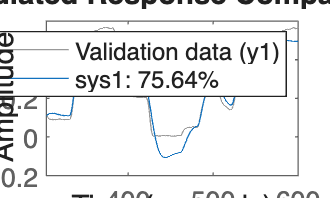


compare(z2f,sys1)

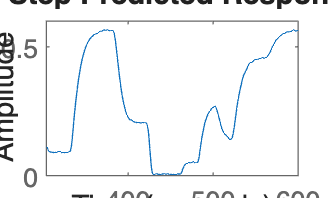

predict(z2f, sys1)